# Projet TS224

## Préliminaires

### Préliminaire 1 : analyser un signal aléatoire stationnaire

#### Rxx théorique et estimés

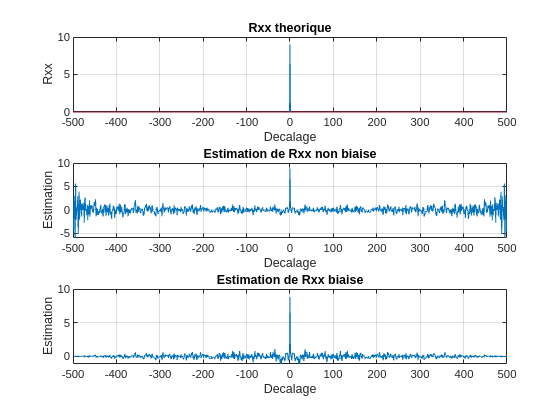

N = 500;
fn = -1/2:1/N:1/2-1/N;

sigma = 3;
m = 0;
x = m + sigma * randn(1, N);

sigma2 = sigma^2;

decalages = -N:N;

Rxx_th = zeros(2*N+1);

Rxx_th(decalages == 0) = sigma2;

[estim_biaise, decalage_b] = xcorr(x, 'biased');

[estim_nonbiaise, decalage_nb] = xcorr(x, 'unbiased');

figure;
subplot(3, 1, 1);
plot(decalages, Rxx_th);
xlabel('Decalage');
ylabel('Rxx');
title('Rxx theorique')
grid on;

subplot(3, 1, 2);
plot(decalage_nb, estim_nonbiaise);
xlabel('Decalage');
ylabel('Estimation');
title('Estimation de Rxx non biaise')
grid on;

subplot(3, 1, 3);
plot(decalage_b, estim_biaise);
xlabel('Decalage');
ylabel('Estimation');
title('Estimation de Rxx biaise')
grid on;

#### DSP et puissance de x

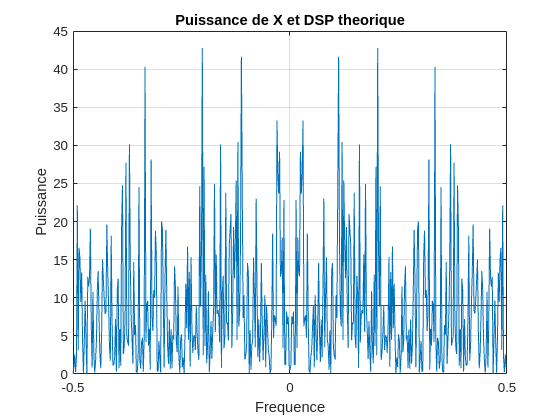

X = fftshift(fft(x));
PX = (abs(X).^2)/N;

DSP = ones(1,N)*sigma2;

figure;
plot(fn, PX);
hold on;
plot(fn, DSP, 'r');
xlabel('Frequence')
ylabel('Puissance')
title('Puissance de X et DSP theorique')
grid on;

#### Périodogramme de Daniell

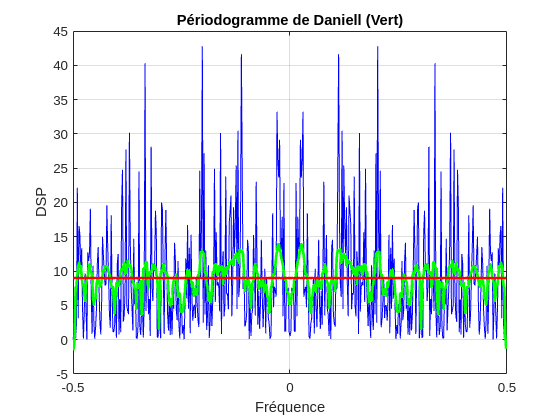

fs = 1;                      

M = 5;
w = ones(1, M) / M;

PX_daniell = conv(PX, w, 'same');

figure;
plot(fn, PX, 'b');
hold on;
plot(fn, 10*log10(PX_daniell), 'g', 'LineWidth', 2);
hold on;
plot(fn, DSP, 'r', 'LineWidth', 2);
title('Périodogramme de Daniell (Vert)');
xlabel('Fréquence');
ylabel('DSP');
grid on;

#### Périodogramme de Bartlett

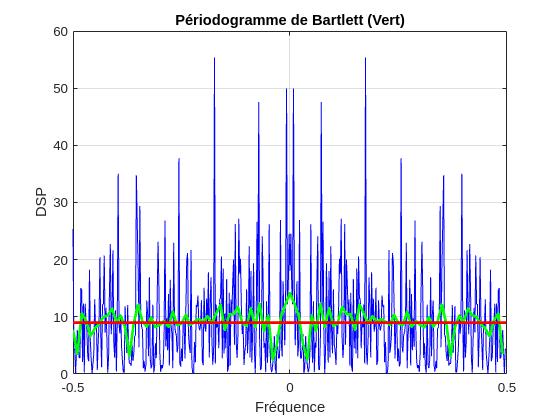

K = 5;
L = floor(N / K);

PX_bartlett = zeros(1, L);

for k = 1:K
    x_seg = x(((k-1)*L + 1):k*L);  
    X_seg = fftshift(fft(x_seg));
    PX_seg = (abs(X_seg).^2)/L;
    PX_bartlett = PX_bartlett + PX_seg;
end

PX_bartlett = PX_bartlett / K;

fn_bartlett = -1/2:1/L:1/2-1/L;

figure;
plot(fn, PX, 'b');
hold on;
plot(fn_bartlett, 10*log10(PX_bartlett), 'g', 'LineWidth', 2);
hold on;
plot(fn, DSP, 'r',  'LineWidth', 2);
title('Périodogramme de Bartlett (Vert)');
xlabel('Fréquence');
ylabel('DSP');
grid on;

#### Périodogramme de Welch

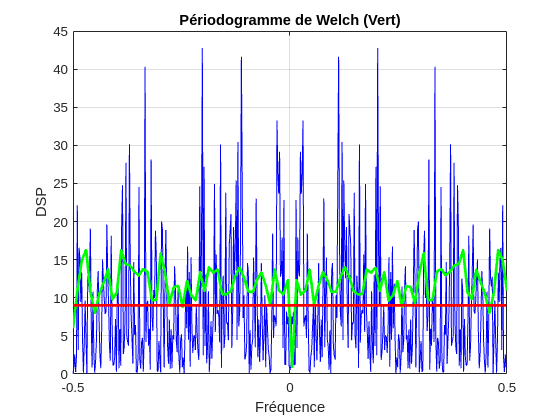

L = 100;
overlap = 50;
w = rectwin(L);

PX_welch = pwelch(x, w, overlap, L, fs);  

PX_welch_full = [flipud(PX_welch); PX_welch(2:end-1)];

f_full = linspace(-fs/2, fs/2, length(PX_welch_full));

figure;
plot(fn, PX, 'b');
hold on;
plot(f_full/fs, 10*log10(fftshift(PX_welch_full)), 'g', 'LineWidth', 2);
hold on;
plot(fn, DSP, 'r',  'LineWidth', 2);
title('Périodogramme de Welch (Vert)');
xlabel('Fréquence');
ylabel('DSP');
grid on;

#### Planitude

planitude = geomean(PX) / mean(PX);
disp(planitude);

    0.5585



Valeurs de planitude obtenues pour sigma = 3 : 0.5441 ; 0.5720 ; 0.5703 ; 0.5738 ; 0.5299 ; 

Valeurs de planitude obtenues pour sigma = 5 : 0.5664 ; 0.5961 ; 0.5510 ; 0.5858 ; 0.5277 ; 

moy_empirique = mean([0.5441, 0.5720, 0.5703, 0.5738, 0.5299, 0.5664, 0.5961, 0.5510, 0.5858, 0.5277]);
ecarttype_empirique = std([0.5441, 0.5720, 0.5703, 0.5738, 0.5299, 0.5664, 0.5961, 0.5510, 0.5858, 0.5277]);
fprintf('Moyenne de la platitude spectrale : %.2f\n', moy_empirique);

Moyenne de la platitude spectrale : 0.56


fprintf('Écart-type de la platitude spectrale : %.3f\n', ecarttype_empirique);

Écart-type de la platitude spectrale : 0.023


#### Planitude périodogramme de Welch

planitude = geomean(PX_welch_full) / mean(PX_welch_full);
disp(planitude);

    0.8807



Valeurs de planitude obtenues pour sigma = 3 : 0.9183 ; 0.9187 ; 0.9234 ; 0.9231 ; 0.9381 ;

Valeurs de planitude obtenues pour sigma = 5 : 0.9276 ; 0.9280 ; 0.9286 ; 0.9435 ; 0.9210 ;

moy_empirique = mean([0.9183, 0.9187, 0.9234, 0.9231, 0.9381, 0.9276, 0.9280, 0.9286, 0.9435, 0.9210]);
ecarttype_empirique = std([0.9183, 0.9187, 0.9234, 0.9231, 0.9381, 0.9276, 0.9280, 0.9286, 0.9435, 0.9210]);
fprintf('Moyenne de la platitude spectrale : %.2f\n', moy_empirique);

Moyenne de la platitude spectrale : 0.93


fprintf('Écart-type de la platitude spectrale : %.3f\n', ecarttype_empirique);

Écart-type de la platitude spectrale : 0.008


#### Planitude théorique 

La planitude théorique vaut 1 car les deux moyenne donne 1 car le spectre de la DSP est plat.

#### Planitude avec la moyenne d'ordre p

p = -5;
moyenne_p = (sum(PX.^p) / length(PX))^(1/p);
planitude = moyenne_p / mean(PX);
disp(planitude);

    0.0111



p → 0 Moyenne géométrique → planitude classique

p > 0 Moyenne pondérée sur les valeurs élevées → planitude plus grande

p < 0 Moyenne pondérée sur les valeurs faibles → planitude plus petite

### Préliminaire 2 : bruiter un signal de parole selon un rapport signal à bruit donné

#### Représentation temporelle et spectrogramme des signaux de paroles bruité et non bruité

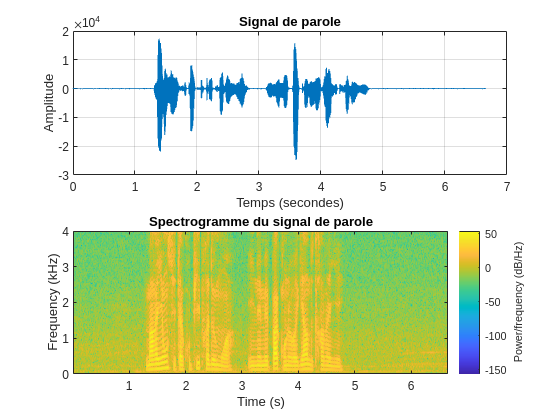

load("fcno03fz.mat")
sp = fcno03fz;
fech = 8000;
%soundsc(sp, fech);
RSB = [5, 10, 15];

%{
for k = 1:length(RSB)
    sp_bruite = ajout_bruit(sp, RSB(k));
    soundsc(sp_bruite, fech);
    pause(length(sp)/fech)
end 
%}

sp_bruite = ajout_bruit(sp, RSB(1));

t = (0:length(sp)-1) / fech;

window = 256;
noverlap = 128;
nfft = 512;

figure;
subplot(2,1,1);
plot(t, sp);
title('Signal de parole');
xlabel('Temps (secondes)');
ylabel('Amplitude');
grid on;
subplot(2,1,2);
spectrogram(sp, window, noverlap, nfft, fech, 'yaxis'); 
title('Spectrogramme du signal de parole');

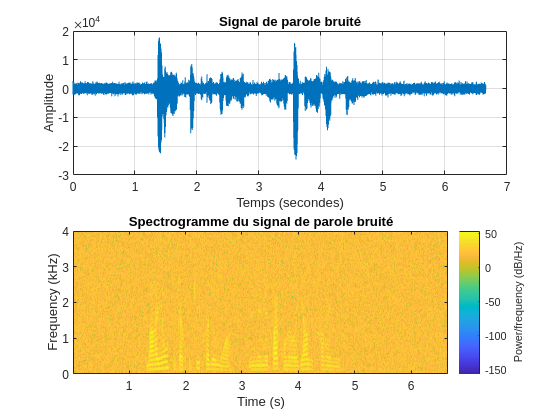

figure;
subplot(2,1,1);
plot(t, sp_bruite);
grid on;
title('Signal de parole bruité');
xlabel('Temps (secondes)'); 
ylabel('Amplitude');
subplot(2,1,2);
spectrogram(sp_bruite, window, noverlap, nfft, fech, 'yaxis');
title('Spectrogramme du signal de parole bruité');  

### Préliminaire 3 : filtrer un signal de parole

load("fcno03fz.mat")
sp = fcno03fz;
fech = 8000;
k0 = [1, 10, 100, 300, 3000, 6000];

%{
for k = 1:length(k0)
    h = zeros(1, k0(k) + 1); 
    h(1) = 1; 
    h(k0(k) + 1) = 1;
    sp_filtered = conv(sp, h);


    soundsc(sp_filtered, fech);
    pause(length(sp)/fech)
end
%}

h = zeros(1, k0(5) + 1); 
h(1) = 1; 
h(k0(5) + 1) = 1;
sp_filtered = conv(sp, h);

t = (0:length(sp)-1) / fech;

t_filtered = (0:length(sp_filtered)-1) / fech;

window = 256;
noverlap = 128;
nfft = 512;

figure;
subplot(2,1,1);
plot(t, sp);
title('Signal de parole');
xlabel('Temps (secondes)');
ylabel('Amplitude');
grid on;
subplot(2,1,2);
spectrogram(sp, window, noverlap, nfft, fech, 'yaxis'); 
title('Spectrogramme du signal de parole');

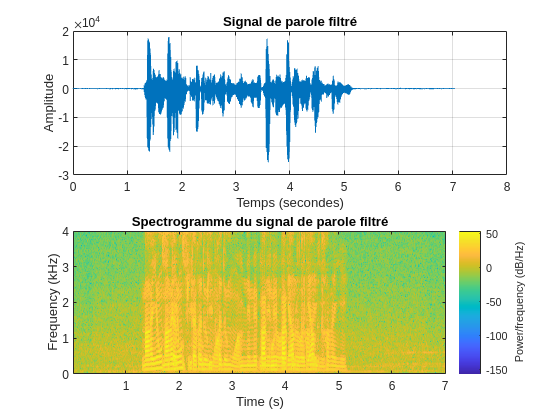


figure;
subplot(2,1,1);
plot(t_filtered, sp_filtered);
grid on;
title('Signal de parole filtré');
xlabel('Temps (secondes)'); 
ylabel('Amplitude');
subplot(2,1,2);
spectrogram(sp_filtered, window, noverlap, nfft, fech, 'yaxis');
title('Spectrogramme du signal de parole filtré');

### Préliminaire 4 : procédure dite d’addition-recouvrement

clear; close all; clc;
load("fcno03fz.mat")
sp = fcno03fz;
sp = sp(:)';

N = 512;
overlap = 0.5; 
starts = N*(1-overlap);

w = ones(1, N);

% Découpage et traitement des trames
numFrames = floor((length(sp)-N)/starts) + 1;
frames = zeros(numFrames, N);

for i = 1:numFrames
    id = (i-1)*starts + 1;
    frames(i,:) = sp(id:id+N-1) .* w;
end

% Reconstruction
sp_reconst = zeros(1, (numFrames-1)*starts + N);
win_sum = zeros(1, length(sp_reconst));

for i = 1:numFrames
    id = (i-1)*starts + 1;
    sp_reconst(id:id+N-1) = sp_reconst(id:id+N-1) + frames(i,:) .* w;
    win_sum(id:id+N-1) = win_sum(id:id+N-1) + w;
end

sp_reconst = sp_reconst ./ win_sum;
sp_reconst = sp_reconst(1:length(sp));

err = sp - sp_reconst;
fprintf("Erreur moyenne = %e\n", mean(abs(err)));

Erreur moyenne = 0.000000e+00


### Cahier des charges

#### Base de données des signaux bruités à trait

clear; close all; clc;
load("fcno03fz.mat")
sp = fcno03fz;
fech = 8000;
RSB = [5, 10, 15];
data_base = zeros(length(RSB), length(sp));
    
    
for k = 1:length(RSB)
  data_base(k,:) = ajout_bruit(sp, RSB(k));
end 
    

#### Traitement de rehaussement trame par trame

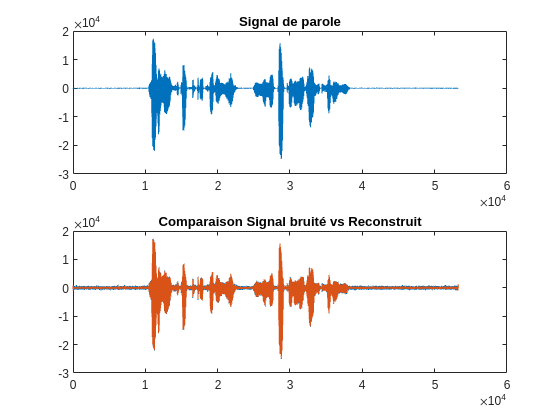

spb = data_base(3,:);
spb = spb(:)'; 
    
N = 512;
overlap = 0.5; 
starts = N*(1-overlap);
    
%w = ones(1, N);
w = hamming(N)';
    
% Calcul de B_2
nb_silence = 5;
B_2_sum = zeros(1,N);
for k = 1:nb_silence
    id = (k-1)*starts + 1;
    Y = fft(spb(id:id+N-1) .* w);
    B_2_sum = B_2_sum + abs(Y).^2;
end
B_2 = B_2_sum / nb_silence;
    
% Découpage et traitement des trames
numFrames = floor((length(spb)-N)/starts) + 1;
frames = zeros(numFrames, N);

for i = 1:numFrames
    id = (i-1)*starts + 1;
    y = spb(id:id+N-1) .* w;
    Y = fft(y);
    
    mod_Y = abs(Y);
    phase_Y = angle(Y);
    
    % Soustraction spectrale
    mod_SP_2 = max(mod_Y.^2 - B_2, 0);
    mod_SP = mod_SP_2.^0.5;
    
    % Reconstruction FFT complexe
    S_estime = mod_SP .* exp(1j*phase_Y);
    
    % FFT inverse
    frames(i,:) = real(ifft(S_estime));
end


% Reconstruction
sp_reconst = zeros(1, (numFrames-1)*starts + N);
win_sum = zeros(1, (numFrames-1)*starts + N);

for i = 1:numFrames
    id = (i-1)*starts + 1;
    sp_reconst(id:id+N-1) = (sp_reconst(id:id+N-1) + frames(i,:));
    win_sum(id:id+N-1) = win_sum(id:id+N-1) + w;
end

sp_reconst = sp_reconst ./ (win_sum);
sp_reconst = sp_reconst(1:length(spb));

figure;
subplot(2,1,1); plot(sp); title("Signal de parole");
subplot(2,1,2); plot(spb); 
hold on;
plot(sp_reconst); title("Comparaison Signal bruité vs Reconstruit")

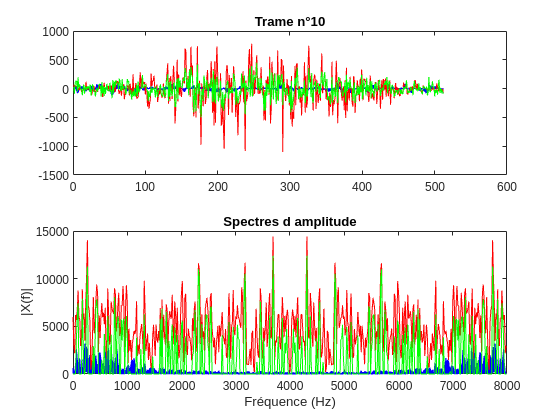

i = 10; % par exemple la 10e trame
id = (i-1)*starts + 1;
trame_originale = sp(id:id+N-1) .* w;
trame_bruitee = spb(id:id+N-1) .* w;
trame_rehaussee = frames(i,:); % issue de ton traitement FFT

% Affichage temporel
figure;
subplot(2,1,1);
plot(trame_originale,'b'); hold on;
plot(trame_bruitee,'r');
plot(trame_rehaussee,'g');
title(['Trame n°' num2str(i)]);

% Affichage spectres
subplot(2,1,2);
f = (0:N-1)*(fech/N);
plot(f,abs(fft(trame_originale)),'b'); hold on;
plot(f,abs(fft(trame_bruitee)),'r');
plot(f,abs(fft(trame_rehaussee)),'g');
title('Spectres d amplitude');
xlabel('Fréquence (Hz)');
ylabel('|X(f)|');

sp = sp(:);
spb = spb(:);
sp_reconst = sp_reconst(:); 

bruit_avant = sp - spb;
puissance_signal = sum(sp.^2);
puissance_bruit_avant = sum(bruit_avant.^2);
rsb_avant = 10 * log10(puissance_signal / puissance_bruit_avant)

rsb_avant = 15.0157


bruit_apres = sp - sp_reconst;
puissance_bruit_apres = sum(bruit_apres.^2);
rsb_apres = 10 * log10(puissance_signal / puissance_bruit_apres)

rsb_apres = 17.8204